# State Space Respresentation 

## DC Motor Speed: System Modeling

[Reference - Link](https://ctms.engin.umich.edu/CTMS/index.php?example=MotorSpeed&section=SystemModeling) 

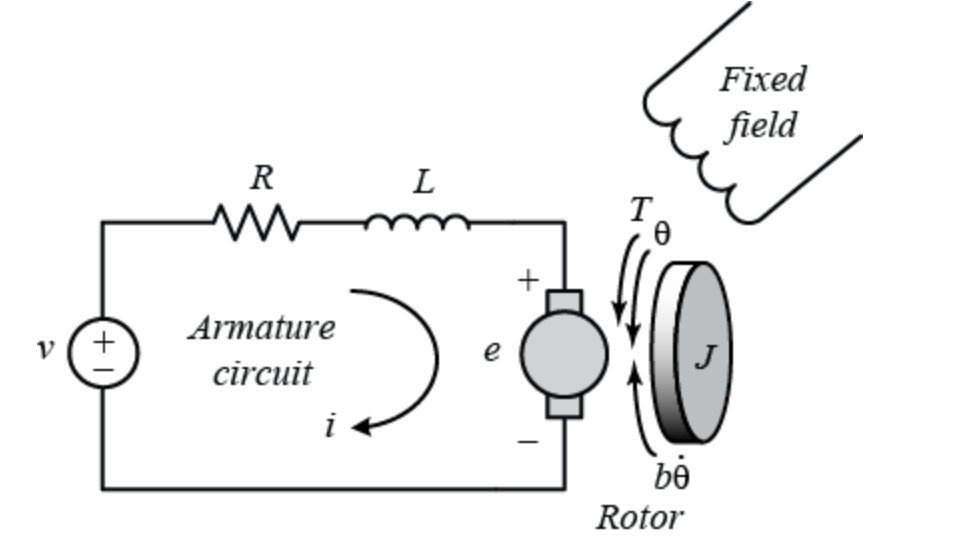

[DC Motor - TF](https://ctms.engin.umich.edu/CTMS/index.php?example=MotorSpeed&section=SystemModeling) 

`(J)     moment of inertia of the rotor     0.01 kg.m^2`

`(b)     motor viscous friction constant    0.1 N.m.s`

`(Ke)    electromotive force constant       0.01 V/rad/sec`

`(Kt)    motor torque constant              0.01 N.m/Amp`

`(R)     electric resistance                1 Ohm`

`(L)     electric inductance                0.5 H`

`K = Ke = Kt;`


$$G\left(s\right)=\frac{K}{\left(\textrm{Js}+b\right)\left(\textrm{Ls}+R\right)+K^2 }$$


J = 0.01;
b = 0.1;
K =0.01;
R = 1;
L = 0.5; 
s = tf('s');
P_motor = K/((J*s+b)*(L*s+R)+K^2)

P_motor =
 
             0.01
  ---------------------------
  0.005 s^2 + 0.06 s + 0.1001
 
Continuous-time transfer function.
Model Properties


## State Space Model 

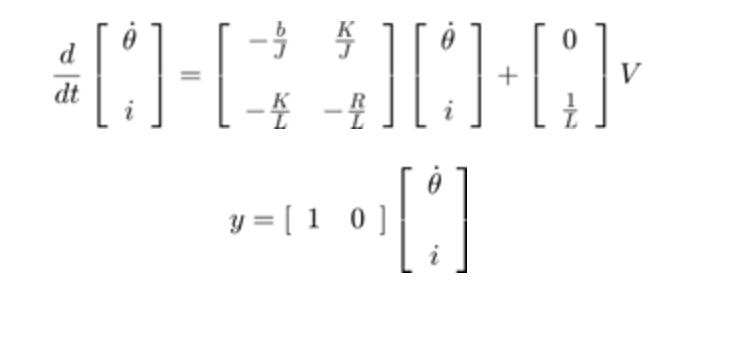

A = [-b/J   K/J
    -K/L   -R/L];
B = [0
    1/L];
C = [1   0];
D = 0;
motor_ss = ss(A,B,C,D)

motor_ss =
 
  A = 
          x1     x2
   x1    -10      1
   x2  -0.02     -2
 
  B = 
       u1
   x1   0
   x2   2
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


## Comparison State Space Model and Transfer function 

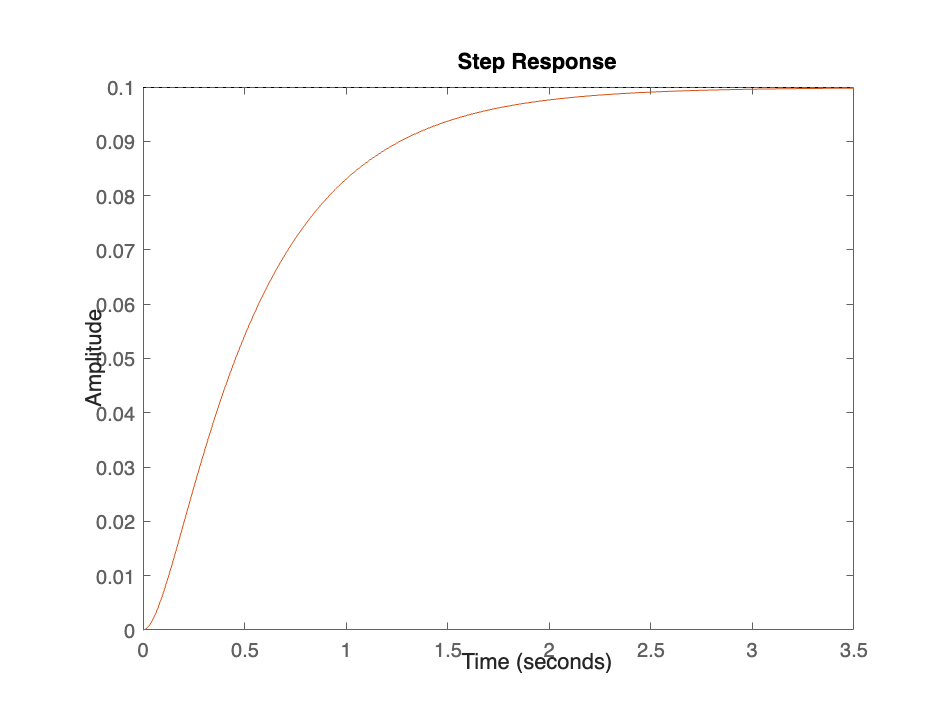

step(P_motor,motor_ss)

## Conversion - between state space and transfer function 

[n,d]= ss2tf(A,B,C,D);
sys_ss2tf = tf(n,d)

sys_ss2tf =
 
          2
  ------------------
  s^2 + 12 s + 20.02
 
Continuous-time transfer function.
Model Properties


P_motor

P_motor =
 
             0.01
  ---------------------------
  0.005 s^2 + 0.06 s + 0.1001
 
Continuous-time transfer function.
Model Properties


[A1, B1, C1, D1] =tf2ss(n,d)

A1 =   -12.0000  -20.0200
    1.0000         0


B1 =      1
     0


C1 =      0     2


D1 = 0

motor_ss

motor_ss =
 
  A = 
          x1     x2
   x1    -10      1
   x2  -0.02     -2
 
  B = 
       u1
   x1   0
   x2   2
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


## State Space response with different initial conditions

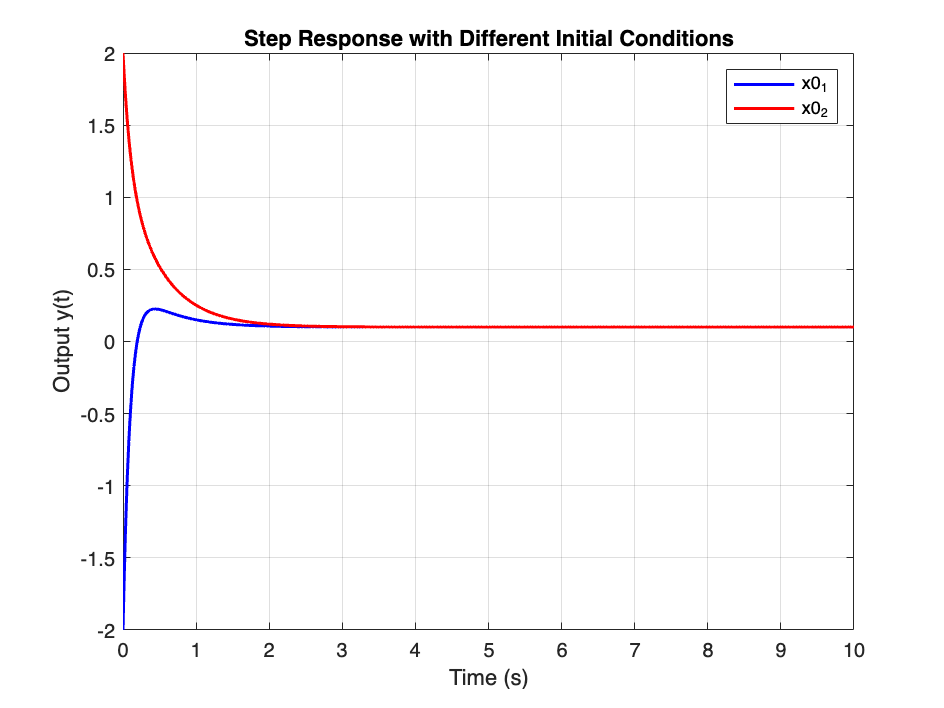

x0_1 = [-2; 4]; % Initial condition 1
x0_2 = [2; 10]; % Initial condition 2
t = 0:0.01:10; % From 0 to 10 seconds
u = ones(size(t));
% Response for initial condition x0_1
[y1, t1, x1] = lsim(motor_ss, u, t, x0_1);

% Response for initial condition x0_2
[y2, t2, x2] = lsim(motor_ss, u, t, x0_2);
figure;
plot(t1, y1, 'b', 'LineWidth', 1.5); hold on;
plot(t2, y2, 'r', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Output y(t)');
legend('x0_1', 'x0_2');
title('Step Response with Different Initial Conditions');
grid on;